# Analisando a onda quadrada

## Boas práticas

clc;                % Limpa a tela
clear all;          % limpa as variáveis
close all;          % fecha as figuras

## Definindo as funções

gp = @(Ap)  Ap;                 % parte positiva da onda quadrada
gn = @(An)  An;                 % parte negativa da onda quadrada

x  = @(n,wo,t) exp(-j*n*wo*t);  % cria a função para cálculo das projeções

## Análise simbólica

syms Ap An t wo T1 T2 T0 n

%%%% Numerador

Num = int(gp(Ap)*x(n,wo,t),t,T1,T2) +  int(gn(An)*x(n,wo,t),t,T2,T0); 

%%%% Denominador

Den = int(x(n,wo,t)*x(n,wo,t),t,T1,T0); 

%%%% detemrina o valor de c

c = Num/Den;


## Análise numérica

Ap = 2;
An = 1;
wo = 2*pi/4;
T1 = 0;
T2 = 2;
T0 = 4;
n  = 3;

c_num = eval(c)

c_num = 5.0000e-01 + 2.7219e+15i

## Visualização

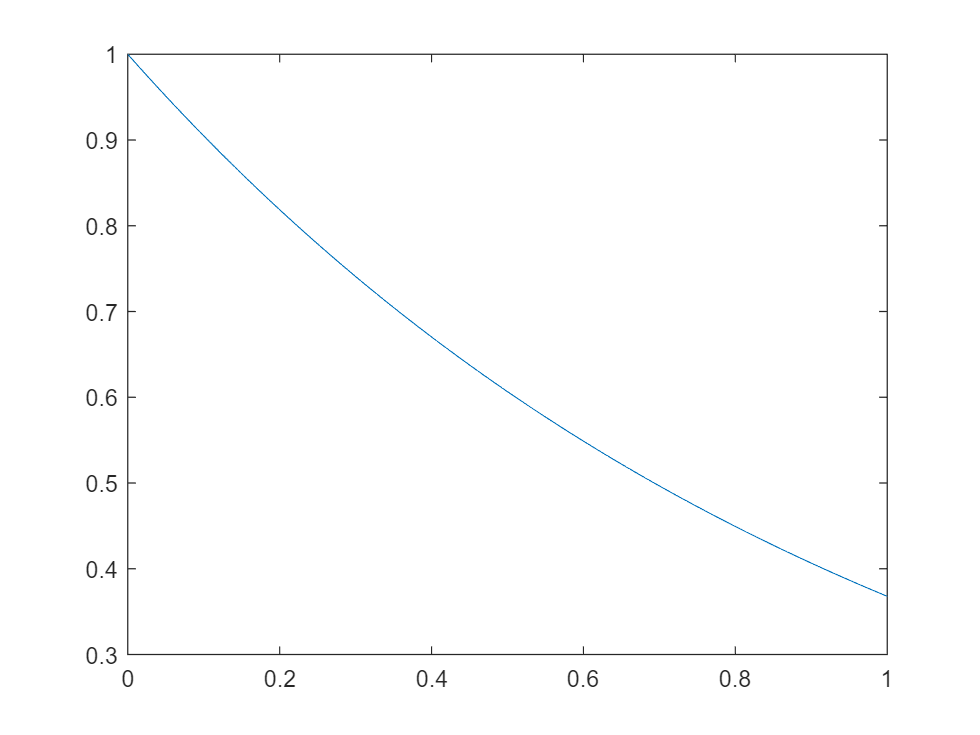


t = [0:1e-3:1];

g = @(t) exp(-t);
y = g(t);

plot(t,y)